# ECM307-G01T02L03D - Atividade P1

## Atividade P1 - Transformada de Fourier

## Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas


## Questão 1.3 - calculando Dn e plotando a reconstrução do sinal

%%%%%%%%%%%%%%%%%%%%%% Questão 1 %%%%%%%%%%%%%%%%%%%%%%
%%% Determinando a transformada de Fourier da onda Triângular do primeiro
%%% item da lista

%% Definindo o sinal triangular - Delta(t), a função gn(t) e inicializando variáveis
    
N = 12;                                      % numero de harmônicas


DeltaPositivo = @(t) (t+2);                    % parte crescente
DeltaNegativo = @(t) (-t+2);                   % parte decrescente
gn            = @(n,t,w0) exp(-j*n*w0*t);      % exponencial de Euler
T0            = 4;                             % periodo ex 1
f0            = (1/T0);                        % frequência ex 1
w0            = 2*pi*f0;                       % frequência angular ex 1
n             = [-N:1:N];                      % vetor de harmônicas
f             = n * f0;                        % vetor de frequências para diferentes valores de n
%%% inicializando vetor tempo para visualizar gráficos
Ts            = T0 * 10^(-3);                  % passo do vetor tempo
tempo         = [-T0/2:Ts:T0/2];               % Vetor tempo para visualização do sinal

%%% Determinação do coeficiente Dn pela integral do Dn
syms t
DnQ1          = (int((DeltaPositivo)*gn(1,t,w0),t,-(T0)/2,0)+int((DeltaNegativo)*gn(1,t,w0),t,0,(T0)/2))/T0;
%%%%%%%%%% pode-se ver que a o resultado para n = 1 é igual ao resultado
%%%%%%%%%% obtido analiticamente
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
DnReal        = eval(DnQ1)

DnReal = 0.4053

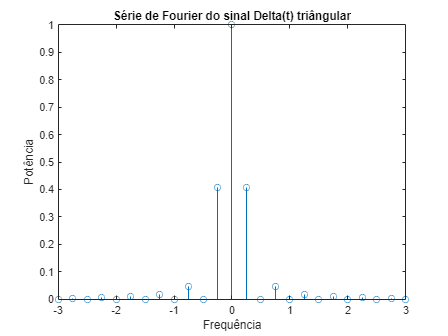

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Determinando o termo Dn simbolicamente

syms n t
%% Utilizando a equação do Dn obtida obtida analiticamente para testar se o cálculo está certo
Dn = 4*(sin(n*pi/2))^2/(n^2*pi^2);
Dn0 = 1;     % Dn0 = valor médio = Área/T0

%% Determinando o termo Dn numericamente

n=[-N:1:N];
 
Dn = eval(Dn);
Dn(N+1) = Dn0;        % Substituindo Dn0 no vetor Dn

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Visualizando no domínio da frequência
figure(1) 
stem(f, abs(Dn));                         % Na frequência o sinal é discreto
title('Série de Fourier do sinal Delta(t) triângular');
xlabel('Frequência');
ylabel('Potência');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pk = 0;
for k = 0 : 2*N   

    pk = pk + Dn(k+1)*exp(j*n(k+1)*w0*tempo);  % sem deslocamento no tempo
   
end
%%% Plotando Delta(t)
figure(2)
plot(tempo,pk,"linewidth", 3)

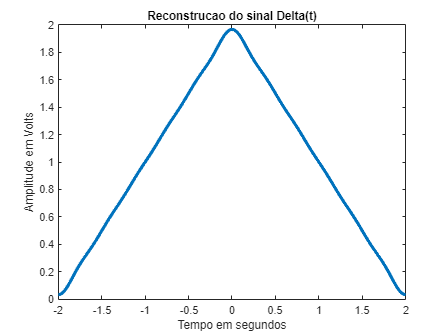

title('Reconstrucao do sinal Delta(t)');
xlabel('Tempo em segundos');
ylabel('Amplitude em Volts');

## Questao 1.4 - Cálculo do número de harmônicas necessário para 95% da potência do sinal

%% Determinando a potência do sinal g(t)
Pg = (int((t+2)^2,t,-2,0) + int((-t+2)^2,t,0,2))/T0;
Pg = eval(Pg)

Pg = 1.3333

%%% Verificando a potência por meio do percentual entre a soma cumulativa dos elementos do
%%% vetor Dn e o Pg

%%  o módulo do Dn_Negativo é igual ao módulo de Dn
%%  portanto, usa-se 2 * abs(Dn) no cálculo

PN = cumsum([1*Dn(N+1)^2,  2*abs(Dn(N+2:end)).^2]); %% Acumula os valores elemento a elemento

for k = 0:2*N
    Pk = PN(k+1);
    percentual = Pk/Pg;
    if(percentual >= 0.95)
        f = Pk * f0
        disp(fprintf("assim o n necessário para a frequência de %f é n = %i", f, k+1))
        break;
    end
end

f = 0.3321

assim o n necessário para a frequência de 0.332128 é n = 2    58



## Questão 2.3 - calculando Dn e plotando a reconstrução do sinal

T0     = 8;                             % periodo ex 2
f0     = (1/T0);                        % frequência ex 2
w0     = 2*pi*f0;                       % frequência angular ex 2
n      = [-N:1:N];                      % vetor de harmônicas
f      = n * f0;                        % vetor de frequências para diferentes valores de n
%%%%%% Calculando Dn e comparando com o analítico
%%% Determinação do coeficiente Dn pela integral do Dn
syms t
Dn1_Q2 = DnQ1*(exp(-j*1*w0*2)-exp(-j*1*w0*6));  % com deslocamento no tempo
Dn1_RealQ2 = eval(Dn1_Q2)

Dn1_RealQ2 = 0.0000 - 0.8106i

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% calculando D2 pela integral obtida analiticamente
DeltaWQ2 = 32/(pi^2)*(exp(-j*pi/2)-exp(-j*3*pi/2))

DeltaWQ2 = 0.0000 - 6.4846i

DnAnalitico = DeltaWQ2/T0

DnAnalitico = 0.0000 - 0.8106i

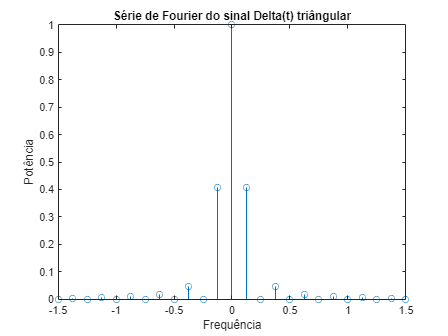

%%%%%%%%% como previsto, o Dn deslocado só tem parte imaginária e é
%%%%%%%%% igual ao calculado analiticamente porém tem o mesmo módulo que o
%%%%%%%%% Dn anterior
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% inicializando vetor tempo para visualizar gráficos
Ts     = T0 * 10^(-3);                  % passo do vetor tempo
tempo  = [0:Ts:T0];                     % Vetor tempo para visualização do sinal

%% calculando Dn2 para exibir gráficos
Dnf2 = Dn.*(exp(-j*n*w0*2)-exp(-j*n*w0*6));  % com deslocamento no tempo

%%% Visualizando no domínio da frequência
figure(3) 
stem(f, abs(Dn));                         % Na frequência o sinal é discreto
title('Série de Fourier do sinal Delta(t) triângular');
xlabel('Frequência');
ylabel('Potência');

%% Determinando Delta(t-2) - Delta(t-6) de forma estruturada 

syms n t

n  = [-N:1:N];
pk = 0;
for k = 0 : 2*N   
    %%%% utilizando Dnf2 calculado com o Dn do exercício anterior
    pk = pk + Dnf2(k+1)*exp(j*n(k+1)*w0*tempo);
end
%%% plotando Delta(t-2) - Delta(t-6)

figure(4)
plot(tempo, pk,"linewidth", 3)

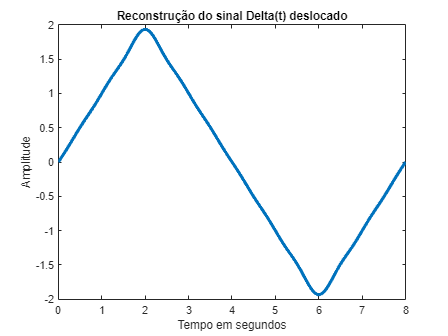

title('Reconstrução do sinal Delta(t) deslocado');
xlabel('Tempo em segundos');
ylabel('Amplitude')

## Questão 2.4 - Cálculo do número de harmônicas necessário para 95% da potência do sinal

%% Determinando a potência do sinal Delta(t-2)-Delta(t-6)
Pg =(int((t)^2,t,0,2)+int((-t+4)^2,t,2,4) + (int((t-4)^2,t,4,6)+int((-t+8)^2,t,6,8)))/T0;
Pg = eval(Pg)

Pg = 1.3333

%%% Verificando a potência por meio do percentual entre a soma cumulativa dos elementos do
%%% vetor Dn e o Pg

%%  o módulo do Dn_Negativo é igual ao módulo de Dn
%%  portanto, usa-se 2 * abs(Dn) no cálculo
%%% help cumsum
%%% cumsum Cumulative sum of elements.
PN = cumsum([1*Dnf2(N+1)^2,  2*abs(Dnf2(N+2:end)).^2]); %% Acumula os valores elemento a elemento

for k = 0:2*N
    Pk = PN(k+1);
    percentual = Pk/Pg;
    if(percentual >= 0.95)
        f = Pk * f0
        disp(fprintf("assim o n necessário para a frequência de %f é n = %i", f, k+1))

        break;
    end
end

f = 0.1643

assim o n necessário para a frequência de 0.164256 é n = 2    58

